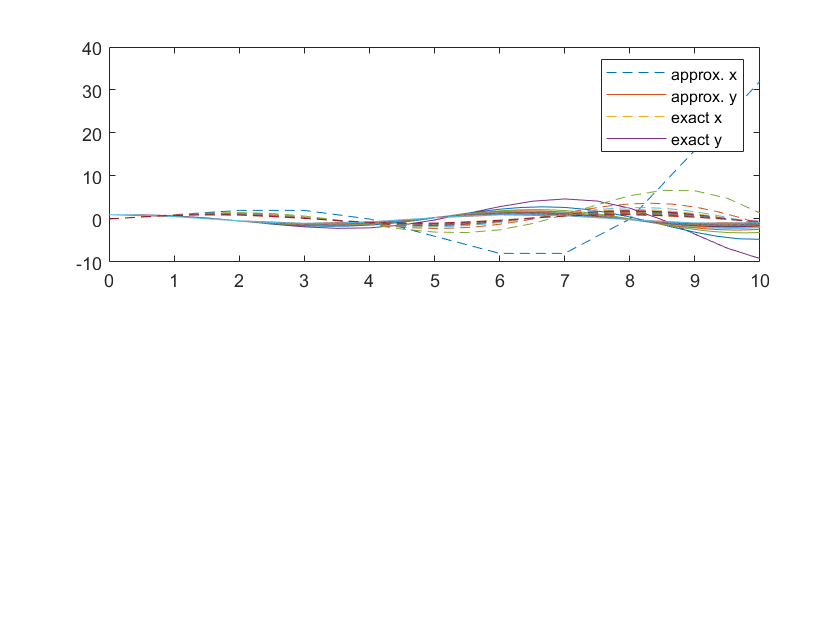

clear
e = 0;
f = -1;
g = 1;
h = 0;
x_0 = 1;
y_0 = 0;
T = 10;
subplot(2,1,1)
for i = 10:10:1000
    N = i;
    dt=T/N;
    t = 0:dt:T;
    [sx,sy] = EMsolver(e,f,g,h,x_0,y_0,T,N);
    vx = cos(t);
    vy = sin(t);
    plot(t,sx,'-')
    plot(t,sy,'--')
    hold on
    plot(t,vx,'-')
    plot(t,vy,'--')
end

legend('approx. x','approx. y','exact x','exact y')

function [x,y] = EMsolver(e,f,g,h,x_0,y_0,T,N)
 A = [e f; g h];
 dt = T/N;
 t = 0:dt:T;

 SOL = NaN(2,length(t));
 SOL(1,1) = x_0;
 SOL(2,1) = y_0;

 for k = 2:length(t)
 SOL(:,k) = SOL(:,k-1) + dt*A*SOL(:,k-1);
 end

 x = SOL(1,:);
 y = SOL(2,:);
end